# Polytope

In CORA, polytopes are instantiated by 

% P = polytope(A,b);

where `A` is the inequality constraint matrix, `b` is the inequality offset vector, and in vertex representation by

% P = polytope(V);

where `V` is a point cloud. 

Example:

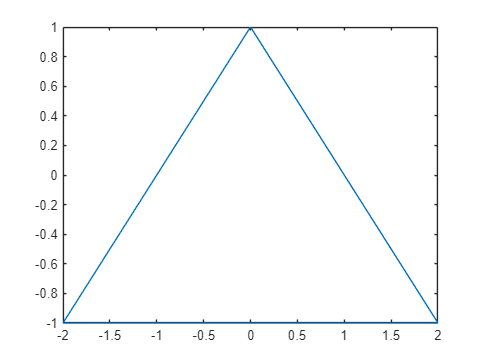

% initialize polytope
A = [1 1; -1 1; 0 -1];
b = [1;1;1];
P = polytope(A,b);

% plot polytope
plot(P);

For more information, type

help polytope

  polytope - object constructor for polytope objects
 
  Description:
     This class represents polytope objects defined as (halfspace
     representation)
       { x | A*x <= b }. 
     For convenience, equality constraints
       { x | A*x <= b, Ae*x == be }
     can be added, too.
     Alternatively, polytopes can be defined as (vertex representation)
       { sum_i a_i v_i | sum_i a_i = 1, a_i >= 0 }
     Note: A polytope without any constraints represents R^n.
     Note: A polytope instantiated without input arguments is the empty set.
 
  Syntax:
     P = polytope(V)
     P = polytope(A,b)
     P = polytope(A,b,Ae,be)
 
  Inputs:
     V - (n x p) array of vertices
     A - (n x m) matrix for the inequality representation
     b - (n x 1) vector for the inequality representation
     Ae - (k x l) matrix for the equality representation
     be - (k x 1) vector for the equality representation
 
  Outputs:
     obj - generated polytope object
 
  Example: 
     A = [1 0 -1 0 1; 0 1 